# Actividad de cierre

Para esta actividad, analizaremos un brazo robótico con 4 grados de libertad, cuyo marco de referencia inercial es como el mostrado a continuación: 

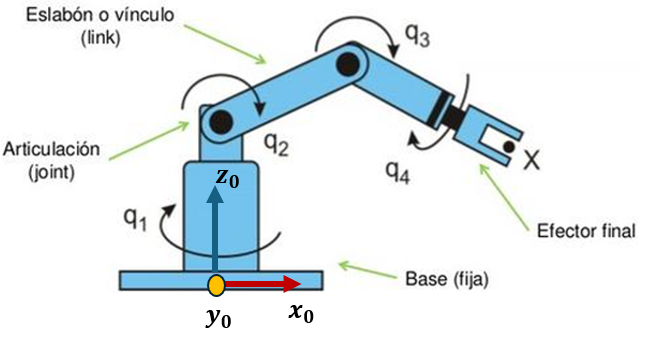

Observemos que el marco de referencia inercial tiene alineado el eje z con la primera articulación, mientras que x es perpendicular a la misma. Notemos que hay un punto amarillo en el sistema de referencias, indicando que y es perpendicular a la pantalla y se dirige a nosotros. 

**Código **

%Limpieza de pantalla
clear all
close all
clc

De igual forma, observemos que nuestro sistema cuenta con 4 variables: 

- theta 1

- theta 2

- theta 3

- theta 4

Recordemos igual que tenemos las constantes l1, l2 y l3 que son las longitudes de cada articulación: 

Porcedemos a declarar las variables simbolicas: 

%Declaración de variables simbólicas 
syms th1(t) th2(t) th3(t) th4(t) l1 l2 l3 l4 t

%configuracion del robot, 0 para junta rotacional y 1 para prismatica 
RP=[0 0 0 0]; 

%Vector de coordenadas articulares
Q = [th1,th2,th3, th4]; 
disp('Coordenadas articulares'); 

Coordenadas articulares


pretty(Q);

(th1(t), th2(t), th3(t), th4(t))





%vector de velocidad articulares
Qp = diff(Q,t); %se utiliza diff para derivadas cuya variable no depende de otras
disp('Velocidades articulares'); 

Velocidades articulares



%numero de grado de libertad del robot
GDL = size(RP,2); %se coloca 2 para referirse a las columnas de la matriz 
GDL_str = num2str(GDL); %convertir numero a string


**Análisis de articulaciones**

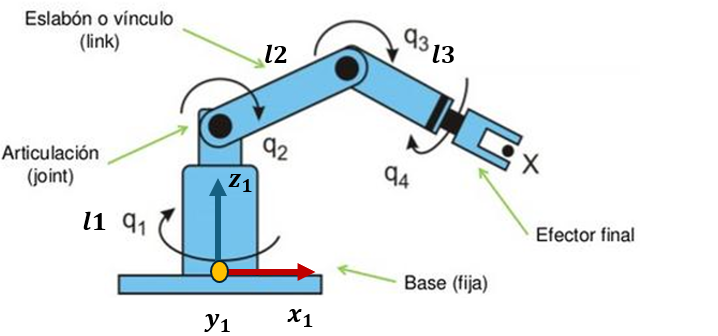

**Articulación 1: **

Traslación: Para la primera articulación, observemos que el sistema debe trasladarse una constante l1 en el eje z con respecto al marco de referencia inercial. 

Rotación: En este caso, observemos que la articuación se encuentra rotando sobre el eje z. Ahora bien, debemos considerar de igual manera que debemos  realizar una modificación o rotación con respecto a este marco de referencia para poder alinearlo con la siguiente junta, de tal manera que el eje z sea perpendicular al siguiente articulación. Para lograr esto, deberemos rotar -90 grados en el eje x: 

%posicion de la junta 1 respecto a 0
P(:,:,1) = [0;
            0; 
            l1];  

% Definir la matriz de rotación original R(:,:,1)
%Rotación sobre la articulación (z): 
Rz_1 =  [cos(th1) -sin(th1) 0; 
      sin(th1) cos(th1) 0; 
      0           0     1];

%Rotación del sistema de -90 grados en x :
Rx_1 =  [1 0 0; 
         0 0 1;
         0 -1 0]; 

R(:,:,1) = Rz_1 * Rx_1; 

**Articulación 2: **

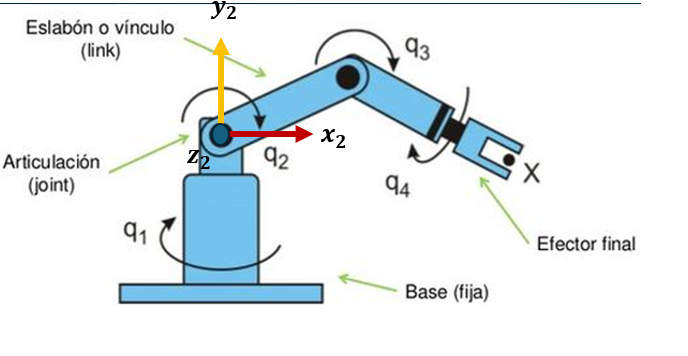

El nuevo marco de referencia que hemos obtenido cuenta con el eje z perpendicular a la pantalla (y a la articulación), alejandose de nostros. 

Traslación: Para llegar a la sigueinte articulación nos deberemos trasladar en x l2*cos(theta2) mientras que en y la traslación será l2*sin(theta2). 

Rotación: Para esta articulación, únicamente deberemos considerar la rotación que realiza la junta sobre el eje z. 

%Articulacion 2
%posicion de la junta 2 respecto a 1
P(:,:,2) = [l2*cos(th2);
            l2*sin(th2); 
            0];  
% Definir la matriz de rotación R(:,:,2)
R(:,:,2) = [cos(th2) -sin(th2) 0; 
            sin(th2) cos(th2) 0; 
             0           0     1];

**Articulación 3: **

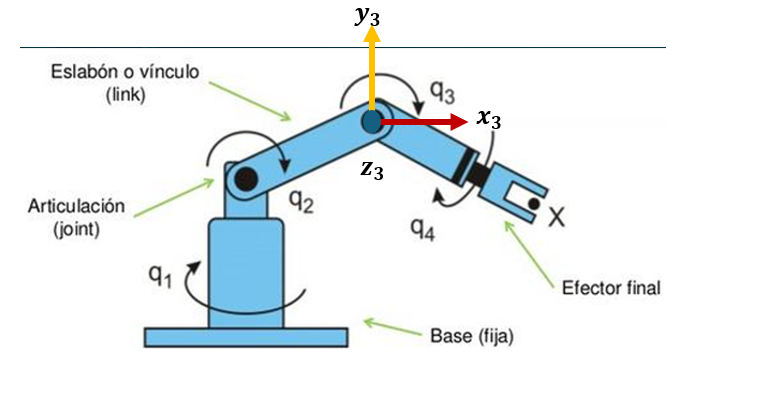

Traslación:  Para llegar a la sigueinte articulación nos deberemos trasladar en x l3*cos(theta3) mientras que en y la traslación será l3*sin(theta3). 

Rotación: Para este caso, el sistema rota sobre el eje z debido al movimiento rotacional de la junta 3. De igual forma, debemos considerar la rotación del sistema de referencias. En este caso, el sistema rota -90 grados en y: 

%posicion de la junta 3 respecto a 2
P(:,:,3) = [l3*cos(th3);
            l3*sin(th3); 
            0]; 

% Definir la matriz de rotación original R(:,:,3)
%Rotación sobre la articulación (z): 
Rz_2 =  [cos(th3) -sin(th3) 0; 
      sin(th3) cos(th3) 0; 
      0           0     1];

%Rotación del sistema de 90 grados en y :
Ry_1 =  [0 0 -1; 
         0 1 0;
         1 0 0]; 

R(:,:,3) = Rz_2 * Ry_1; 


**Articulación 4: **

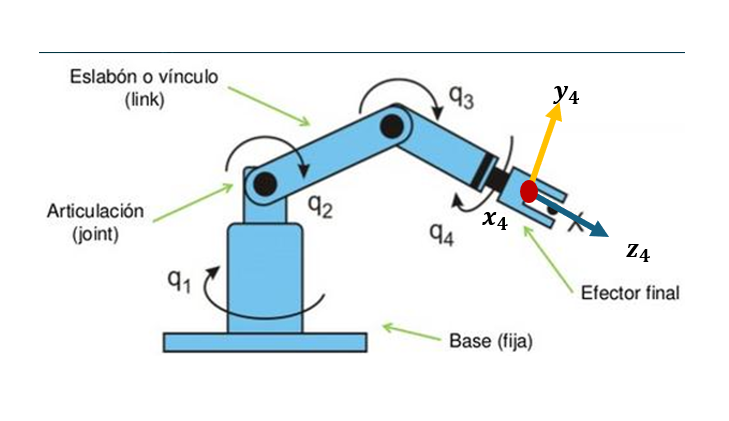

El eje x se encuentra perpendicular a la pantalla, apuntando hacian nosotros. 

Traslación: El sistema se traslada una constante l4 en z.

Rotación: El sistema rota sobre el eje z. 

%posicion de la junta 4 respecto a 3
P(:,:,4) = [0; 
            0; 
            l4]; 

% Definir la matriz de rotación original R(:,:,4)
%Rotación sobre la articulación (z): 
R(:,:,4) =  [cos(th3) -sin(th3) 0; 
      sin(th3) cos(th3) 0; 
      0           0     1];



**Cálculo de velocidades lineales y angulares: **


Vector_Zeros = zeros(1,3); 

%inicializamos matriz de transformacion homogenea local
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%inicializamos matriz de transformacion homogenea global ()
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

PO(:,:,GDL)= P(:,:,GDL); %vectores de posicion vistos desde el marco de referencia inercial

RO(:,:,GDL)= R(:,:,GDL); %matrices de rotacion distas desde el marco de referencia inercial

for i= 1: GDL
    i_str = num2str(i);
    %locales
    %disp(strcat('Matriz de transformacion local A',i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    %pretty (A(:,:,i));

    %globales
    try 
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch 
        T(:,:,i) = A(:,:,i); %caso especifico cuando i= 1 nos marcaria error en try
    end 
    disp(strcat('Matriz de transformacion global T',i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));

    %obtenemos la matriz de rotacion RO y el vector de translacion PO de la
    %matriz de transformacion homogenea global T(:,:,GDL)

    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end 

Matriz de transformacion global T1


/ cos(th1(t)),  0, -sin(th1(t)),  0 \
|                                   |
| sin(th1(t)),  0,  cos(th1(t)),  0 |
|                                   |
|      0,      -1,       0,      l1 |
|                                   |
\      0,       0,       0,       1 /



/ cos(th1(t)),  0, -sin(th1(t)) \
|                               |
| sin(th1(t)),  0,  cos(th1(t)) |
|                               |
\      0,      -1,       0      /



/  0 \
|    |
|  0 |
|    |
\ l1 /



Matriz de transformacion global T2


/ cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), -sin(th1(t)), l2 cos(th1(t)) cos(th2(t)) \
|                                                                                             |
| cos(th2(t)) sin(th1(t)), -sin(th1(t)) sin(th2(t)),  cos(th1(t)), l2 cos(th2(t)) sin(th1(t)) |
|                                                                                             |
|       -sin(th2(t)),            -cos(th2(t)),             0,          l1 - l2 sin(th2(t))    |
|                                                                                             |
\            0,                        0,                  0,                   1             /



/ cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), -sin(th1(t)) \
|                                                                 |
| cos(th2(t)) sin(th1(t)), -sin(th1(t)) sin(th2(t)),  cos(th1(t)) |
|                                                                 |
\       -sin(th2(t)),            -cos(th2(t)),             0      /



/ l2 cos(th1(t)) cos(th2(t)) \
|                            |
| l2 cos(th2(t)) sin(th1(t)) |
|                            |
\     l1 - l2 sin(th2(t))    /



Matriz de transformacion global T3


/ -sin(th1(t)), -cos(th1(t)) sin(#2), -cos(th1(t)) cos(#2),          cos(th1(t)) #1          \
|                                                                                            |
|  cos(th1(t)), -sin(th1(t)) sin(#2), -sin(th1(t)) cos(#2),          sin(th1(t)) #1          |
|                                                                                            |
|       0,            -cos(#2),              sin(#2),       l1 - l2 sin(th2(t)) - l3 sin(#2) |
|                                                                                            |
\       0,                0,                    0,                          1                /

where

   #1 == l2 cos(th2(t)) + l3 cos(#2)

   #2 == th2(t) + th3(t)




/ -sin(th1(t)), -cos(th1(t)) #1, -cos(th1(t)) #2 \
|                                                |
|  cos(th1(t)), -sin(th1(t)) #1, -sin(th1(t)) #2 |
|                                                |
\       0,            -#2,              #1       /

where

   #1 == sin(th2(t) + th3(t))

   #2 == cos(th2(t) + th3(t))




/ cos(th1(t)) (l2 cos(th2(t)) + l3 cos(th2(t) + th3(t))) \
|                                                        |
| sin(th1(t)) (l2 cos(th2(t)) + l3 cos(th2(t) + th3(t))) |
|                                                        |
\      l1 - l2 sin(th2(t)) - l3 sin(th2(t) + th3(t))     /



Matriz de transformacion global T4


[[- cos(th3(t)) sin(th1(t)) - cos(th1(t)) sin(th3(t)) sin(#2), sin(th1(t)) sin(th3(t)) - cos(th1(t)) cos(th3(t)) sin(#2),

  -cos(th1(t)) cos(#2), cos(th1(t)) #1 - l4 cos(th1(t)) cos(#2)],

  [cos(th1(t)) cos(th3(t)) - sin(th1(t)) sin(th3(t)) sin(#2), - cos(th1(t)) sin(th3(t)) - cos(th3(t)) sin(th1(t)) sin(#2),

  -sin(th1(t)) cos(#2), sin(th1(t)) #1 - l4 sin(th1(t)) cos(#2)],

  [-sin(th3(t)) cos(#2), -cos(th3(t)) cos(#2), sin(#2), l1 - l2 sin(th2(t)) - l3 sin(#2) + l4 sin(#2)],

  [0, 0, 0, 1]]

where

   #1 == l2 cos(th2(t)) + l3 cos(#2)

   #2 == th2(t) + th3(t)




[[- cos(th3(t)) sin(th1(t)) - cos(th1(t)) sin(th3(t)) sin(#1), sin(th1(t)) sin(th3(t)) - cos(th1(t)) cos(th3(t)) sin(#1),

  -cos(th1(t)) cos(#1)],

  [cos(th1(t)) cos(th3(t)) - sin(th1(t)) sin(th3(t)) sin(#1), - cos(th1(t)) sin(th3(t)) - cos(th3(t)) sin(th1(t)) sin(#1),

  -sin(th1(t)) cos(#1)],

  [-sin(th3(t)) cos(#1), -cos(th3(t)) cos(#1), sin(#1)]]

where

   #1 == th2(t) + th3(t)




/                    cos(th1(t)) #1 - l4 cos(th1(t)) #2                   \
|                                                                         |
|                    sin(th1(t)) #1 - l4 sin(th1(t)) #2                   |
|                                                                         |
\ l1 - l2 sin(th2(t)) - l3 sin(th2(t) + th3(t)) + l4 sin(th2(t) + th3(t)) /

where

   #1 == l2 cos(th2(t)) + l3 #2

   #2 == cos(th2(t) + th3(t))





%Calculamos el jacobiano lineal y angular de forma analitica
%inicializamod jacobianos analiticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k=1:GDL
    if((RP(k)==0)|(RP(k)==1))

        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1)); %Producto cruz
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1]; %No hay matriz de rotacion anterior, se imprime la matriz de identidad
        end
    else
        %articulaciones prismaticas
       try
           Jv_a(:,k)= RO(:,3,k-1);
       catch
           Jv_a(:,k)=[0,0,1];
       end
           Jw_a(:,k)=[0,0,0];
    end
end

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ l4 sin(th1(t)) cos(#4) - sin(th1(t)) #2,        -cos(th1(t)) #1,       -cos(th1(t)) sin(#4) (l3 - l4), 0 \
|                                                                                                          |
| cos(th1(t)) #2 - l4 cos(th1(t)) cos(#4),        -sin(th1(t)) #1,       -sin(th1(t)) sin(#4) (l3 - l4), 0 |
|                                                                                                          |
\                    0,                    l4 cos(#4) - l3 cos(#4) - #3,       -cos(#4) (l3 - l4),       0 /

where

   #1 == l2 sin(th2(t)) + l3 sin(#4) - l4 sin(#4)

   #2 == #3 + l3 cos(#4)

   #3 == l2 cos(th2(t))

   #4 == th2(t) + th3(t)




disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, -sin(th1(t)), -sin(th1(t)), -cos(th1(t)) cos(th2(t) + th3(t)) \
|                                                                  |
| 0,  cos(th1(t)),  cos(th1(t)), -sin(th1(t)) cos(th2(t) + th3(t)) |
|                                                                  |
\ 1,       0,            0,             sin(th2(t) + th3(t))       /



disp('Velocidad lineal obtenida mediante el Jacobiano Lineal');

Velocidad lineal obtenida mediante el Jacobiano Lineal


V= simplify(Jv_a*Qp'); 
pretty(V); 

/ - #3 sin(th1(t)) #4 - #2 cos(th1(t)) #5 - #1 cos(th1(t)) sin(#6) (l3 - l4) \
|                                                                            |
|  #3 cos(th1(t)) #4 - #2 sin(th1(t)) #5 - #1 sin(th1(t)) sin(#6) (l3 - l4)  |
|                                                                            |
\                       - #2 #4 - #1 cos(#6) (l3 - l4)                       /

where

         _________
          d
   #1 == -- th3(t)
         dt

         _________
          d
   #2 == -- th2(t)
         dt

         _________
          d
   #3 == -- th1(t)
         dt

   #4 == l2 cos(th2(t)) + l3 cos(#6) - l4 cos(#6)

   #5 == l2 sin(th2(t)) + l3 sin(#6) - l4 sin(#6)

   #6 == th2(t) + th3(t)





disp('Velocidad angular obtenido mediante el Jacobiano angular')

Velocidad angular obtenido mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ - #4 sin(th1(t)) - #3 sin(th1(t)) - #1 cos(th1(t)) cos(#2) \
|                                                            |
|  #4 cos(th1(t)) + #3 cos(th1(t)) - #1 sin(th1(t)) cos(#2)  |
|                                                            |
|                   _________                                |
|                    d                                       |
|                   -- th1(t) + #1 sin(#2)                   |
\                   dt                                       /

where

         _________
          d
   #1 == -- th4(t)
         dt

   #2 == th2(t) + th3(t)

         _________
          d
   #3 == -- th3(t)
         dt

         _________
          d
   #4 == -- th2(t)
         dt




**RESULTADOS: **

**Velocidad lineal:**

 Las velocidades lineales resultan más complejas de analizar que las angulares, pues consideran una gran cantidad de componentes en cada uno de los ejes. Es importante mencionar que debido a que se trata de un robot de 4 gdl, el análisis analítico puede ser muy complejo de estudiar, pues como ya mencionamos, considera componentes con base en funciones trigonométricas (seno y coseno). Sin embargo, para poder analizar y comprobar que el resultado de nuestras matrices estudiaremos la velocidad angular.  

**Velocidad angular:  **

Resulta más sencillo analizar el vector de velocidades angulares. Observemos que la velocidad angular en el eje x y en el eje y es considerablemente más compleja a la de la velocidad en z. Esto se debe a la manera en la que consideramos nuestro sistema de referencias, involucrando una gran cantidad de variables y componentes. Para verlo de una manera más sencilla, supongamos un caso en el que la primera junta rota lo suficiente para que el el resto de las articulaciones se alineen a alguno de los otros ejes, provocando así que exista velocidad angular en algún otro eje(x,y). Entraremos más a detalle con el análisis de la velocidad angular para el eje z. En este caso, observemos que se compone de una suma/resta (depende del sistema de referencia) entre dos valores. El primero de los valores es simplemente la derivada de theta1, que es el ángulo de la primera junta rotacional (de revolución) de nuestro sistema. Ahora bien, el segundo valor involucrado es más interesante, ya que considera los valores de theta2, theta3 y theta4, pero ¿por qué? Esto se debe a la componente en z de la velocidad angular del efector final. Esto lo podemos observar si consideramos a theta2 y theta3 como 45 grados. En este caso, el efector final estará alineado con el eje z y, para este caso específico, la velocidad angular se podría reducir como la derivada de theta1 más (o menos) la derivada de theta2. 